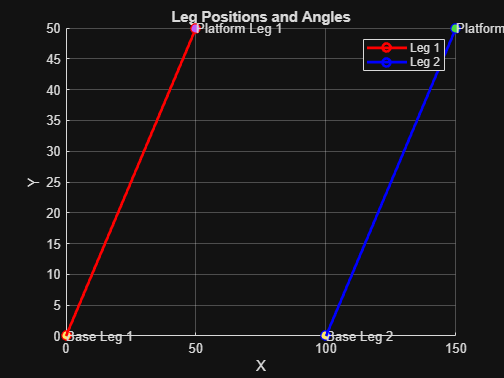

clc;
clear all;

% Example Inputs
Rot = eye(3); % Identity rotation matrix
TVect = [0; 0; 0]; % No translation
BP = [0, 100, 0, 100, 50, 50; 0, 0, 100, 100, 50, 50; 0, 0, 0, 0, 0, 0]; % Base points
PP = [50, 150, 50, 150, 100, 100; 50, 50, 150, 150, 100, 100; 50, 50, 50, 50, 50, 50]; % Platform points

% Call the function to plot
plot_two_legs(Rot, TVect, BP, PP);

function plot_two_legs(Rot, TVect, BP, PP)
    % Calculate new angles
    new_angles = calcAngles(Rot, TVect, BP, PP);

    % Extract positions for two legs
    leg1_base = BP(:,1);
    leg1_platform = TVect + Rot*PP(:,1);

    leg2_base = BP(:,2);
    leg2_platform = TVect + Rot*PP(:,2);

    % Plot the base and platform points
    figure;
    hold on;
    grid on;
    
    % Plot leg 1
    plot3([leg1_base(1), leg1_platform(1)], [leg1_base(2), leg1_platform(2)], [leg1_base(3), leg1_platform(3)], 'r-o', 'LineWidth', 2);
    % Plot leg 2
    plot3([leg2_base(1), leg2_platform(1)], [leg2_base(2), leg2_platform(2)], [leg2_base(3), leg2_platform(3)], 'b-o', 'LineWidth', 2);

    % Plot base points
    scatter3(BP(1,1:2), BP(2,1:2), BP(3,1:2), 'filled');
    % Plot platform points
    scatter3(leg1_platform(1), leg1_platform(2), leg1_platform(3), 'filled');
    scatter3(leg2_platform(1), leg2_platform(2), leg2_platform(3), 'filled');

    % Annotate the plot
    text(leg1_base(1), leg1_base(2), leg1_base(3), 'Base Leg 1');
    text(leg1_platform(1), leg1_platform(2), leg1_platform(3), 'Platform Leg 1');
    text(leg2_base(1), leg2_base(2), leg2_base(3), 'Base Leg 2');
    text(leg2_platform(1), leg2_platform(2), leg2_platform(3), 'Platform Leg 2');
    
    xlabel('X');
    ylabel('Y');
    zlabel('Z');
    title('Leg Positions and Angles');
    legend('Leg 1', 'Leg 2');
    
    hold off;
end

function new_angles  = calcAngles(Rot, TVect, BP, PP)
    % Length of operational length
    s_leg = 119.0; % repmat(119.0, 1, 6);
    % Length of servo arm
    a_leg = 21.0; % repmat(21.0, 1, 6);

    % Definition of the platform home position
    h= sqrt(s_leg.^2+ a_leg.^2 -(PP(1,:) - BP(1,:)).^2 - (PP(2,:) - BP(2,:)).^2) -PP(3,:);
    home_pos= [0, 0, h(1)]';
    leg = zeros(3,6);
    leg_length = zeros(1,6);
    
    % Calculate effective rod length in Base System for all 6 rods
    for i=1:6
        % l_B Vector + home_pos
        leg(:,i) = TVect + Rot*PP(:,i) - BP(:,i);
        leg_length(i)= norm(leg(:,i));
    end

    % Get coordinates of the points where the rod is attached to the platform 
    x_P= leg(1,:) + BP(1,:);
    y_P= leg(2,:) + BP(2,:);
    z_P= leg(3,:) + BP(3,:);

    x_B= BP(1,:);
    y_B= BP(2,:);
    z_B= BP(3,:);
    beta = deg2rad([240, 240, 120, 120, 0, 0]);

    % Calculate auxiliary quatities
    L= leg_length.^2 - s_leg.^2 + a_leg.^2;
    M= 2*a_leg*(z_P - z_B);
    N= 2*a_leg*(cos(beta).*(x_P - x_B) + sin(beta).*(y_P - y_B));
    x = (L./sqrt(M.*M + N.*N));
    new_angles= asin(mod(x,1)) - atan2(N,M);
end
